# Construct a toy model of solar wind E field (and not the transfer function), with apppropriate ACF

Demonstrates that the non-linear relationship observed between SML and Em can be explained by PDF of Em, and the uncertainty in the propagation delays.

Result: Electric field measured is an over-estimate by a large margin Current in the ionosphere for a given E-field of 40 mV is 3 times smaller than the true current! See FigureX1.m & FigureX1a.m

## Extract OMNI for SML

omniFile = 'G:\My Drive\Research\Projects\Data\omni.h5';
omni = extract_omni_data(omniFile);


% Extract error and X pdf from data
dataFolder = 'G:\My Drive\Research\Projects\Data\omni_components\';
geotail1 = extract_set_of_data(dataFolder,'geotail');
wind1 = extract_set_of_data(dataFolder,'wind');
ace1 = extract_set_of_data(dataFolder,'ace');

% ACE, WIND, GEOTAIL, time conjunctions
[~,~,wi]=intersect(geotail1.datetime,wind1.datetime);
[~,ai,wii]=intersect(ace1.datetime,wind1.datetime(wi));
[~,gi,~]=intersect(geotail1.datetime,wind1.datetime(wi(wii)));
wi = wi(wii);

% ACE, WIND, GEOTAIL conjunction tables
ace = ace1(ai,:);
wind = wind1(wi,:);
geotail = geotail1(gi,:);

## Data

Input X, and output Y as real measurements

time_S = wind.datetime; 
XmSa = wind.E_sw*10^-3; % Measurement with error, from Wind s/c
XS = geotail.E_sw*10^-3;% True value (as close to true value we can get)
eS = XmSa - XS;         % Error in the measurements between the two spacecraft
eNormS = eS./XS;        % Normalized by their magnitudes
YS = omni.Fsml(datenum(time_S)); % Ionospheric currents

% Finding ACF of X, from data
[Me, nSample,  nEnsemble]  = split_series(wind1.E_kl.*10^-3,2^13);
[RArraye,lage] = find_correlation(Me-nanmean(Me,1),nSample,nEnsemble,1);

acf_E = mean(RArraye(:,1:2^12)./RArraye(:,1));
lag_E = lage(1:2^12);
acf_fit = fit(lag_E,acf_E','spline'); % Fitting the ACF with a spline!

## Developing the Toy Model

Constructing a random variable X, with log normal distribution and the above ACF

dt = 1; % 1 min intervals
nSamples = 2^12; % Upto 80 hours
nEnsembles=1000;
lag = fftshift(-nSamples:1:nSamples-1)'.*dt;
Rm = acf_fit(abs(lag));
% Input 2 : The autocorrelation matrix/function
RmMatrix = toeplitz(Rm(find(lag==0):find(lag==(nSamples-1)*dt)));

% The desired random variable 
% Input 1 : Random variable X, with log-normal distribution and the above
%           ACF
% pdfx = makedist('Lognormal',-0.286163,0.789428);
% X = MvLogNRand(repmat(-0.286163,nSamples,1),repmat(0.789428,nSamples,1),nEnsembles,RmMatrix);
X = MvtRand( repmat(0.104846, nSamples, 1) , 5.41353 , repmat(1.25289, nSamples, 1), nEnsembles , RmMatrix);
[RArrayX,lageX] = find_correlation(X-nanmean(X,1),nSamples,nEnsembles,1);
% X = MvNRand(repmat(0.0877612,nSamples,1),repmat(1.55837,nSamples,1),nEnsembles,RmMatrix);


% X = MvLogNRand(repmat(-0.286163,nSamples,1),repmat(1.09028,nSamples,1),nEnsembles,RmMatrix);
% This is approximated to be the true variable of interest
% Log-normal distribution was arrived at from using Geotail, <5 RE from nose

% Using X, and ACF, calculating the errors
time = 1:1:nSamples;
% Input 3: The error due to propagation delay from L1 to Nose, and Nose
% to Ionosphere
sigma_L1_N = 8; %8 minutes
sigma_N_I = 20; %20 minutes
% Temporal uncertainty due to propagation delay from L1 to Nose
% terr_L1_N = (random('Weibull',sigma_L1_N,0.5,nSamples,nEnsembles))';
% terr_L1_N = (random('Half Normal',0,6,nSamples,nEnsembles))';
s=1;
m=1;
terr_L1_N = (random('Lognormal',log(s.^2./(s.^2+m.^2).^0.5),sqrt(log(1+s.^2./m.^2)),nSamples,nEnsembles))';
time_L1_N = time - terr_L1_N;
% Temporal uncertainty due to propagation delay from Nose to Ioonosphere
% terr_N_I = (random('Weibull',sigma_N_I,5,nSamples,nEnsembles))';
terr_N_I = (random('Weibull',sigma_N_I,4,nSamples,nEnsembles))';
time_L1_I = time - terr_L1_N - terr_N_I; 
% Using the temporal uncertainty, calculating the error-prone 
% measurement X
X_L1_N = zeros(nEnsembles,nSamples);
X_L1_I = zeros(nEnsembles,nSamples);
for i=1:1:nEnsembles
    X_L1_N(i,:) = interp1(time',X(i,:)',time_L1_N(i,:)')';
    X_L1_I(i,:) = interp1(time',X(i,:)',time_L1_I(i,:)')';
end
e_L1_N = X_L1_N - X; % Error in X, due to propagation delay from L1 to nose
eNorm_L1_N = e_L1_N./X; 

e_L1_I = X_L1_I - X; % Error in X, due to propagation delay from L1 to ionosphere
eNorm_L1_I = e_L1_I./X;

% Fitting a probability density function on the normalized error
pdfe = fitdist(eNorm_L1_N(:),'kernel'); 
pdfeTotal = fitdist(eNorm_L1_I(:),'kernel');

% Generating samples of the error varible
U = random(pdfe,nSamples,nEnsembles)'; % Normalized error (almost homoscedastic)
UT = random(pdfeTotal,nSamples,nEnsembles)';

% The ERROR MODEL
W = X + abs(X).*U; % Errorneous measurements made by WIND-like spacecraft (L1 to nose)
Wa = X + abs(X).*random(pdfe,nSamples,nEnsembles)'; % Another spacecraft measurement (like ACE)

WT = X + abs(X).*UT; % Total error, L1 to Ionosphere
WTa = X + abs(X).*random(pdfeTotal,nSamples,nEnsembles)'; % Another spacecraft measurement (like ACE)

e = W - X; % Calculating the error in the toy model
e2 = W - Wa;

eT = WT - X; % Total error from L1 to ionosphere, in the toy model
eT2 = WT - WTa;

eNorm = e./X; % Type 1 - difference between errenous measurements and true-value
eNorm2 = e2./X; % Type 2 - difference between two errenous measurements

eNormT = eT./X; % Normalized version of the total error
eNormT2 = eT2./X;

% Checking if ACFs makes sense
% Problem here, the average in the line is taken across the ensembles
% but while calculating the ACF from real data, it is taken across the
% samples (:/). Which is right? Why do they match more closely than when we
% take the same?\

% Calculating ACFs from the toy-model

[RArrayW,lageW] = find_correlation(W-nanmean(W,1),nSamples,nEnsembles,1);
[RArrayWT,lageWT] = find_correlation(WT-nanmean(WT,1),nSamples,nEnsembles,1);

% Calculating conditional probability distributions
[PegX,XPegX,YPegX] = conditional_pdf(e(:),X(:),-5:0.1:5,-20:1:20);
[PeNgX,XPeNgX,YPeNgX] = conditional_pdf(eNorm(:),X(:),-5:0.1:5,-20:1:20);

[PeTgX,XPeTgX,YPeTgX] = conditional_pdf(eT(:),X(:),-5:0.1:5,0:1:20);
[PeNTgX,XPeNTgX,YPeNTgX] = conditional_pdf(eNormT(:),X(:),-5:0.1:5,-20:1:20);

[PeSgXS,XPeSgXS,YPeSgXS] = conditional_pdf(eS,XS,-5:0.1:5,-20:1:20);
[PeNSgXS,XPeNSgXS,YPeNSgXS] = conditional_pdf(eNormS,XS,-5:0.1:5,-20:1:20);

% Calculating conditional expectations
XBins = -30:1:30;
EXgW = create_curve(W(:),X(:),XBins);
EXgX = create_curve(X(:),X(:),XBins);
EXgWT = create_curve(WT(:),X(:),XBins);
EYSgXm = create_curve(XmSa,YS,XBins);

% Calculating the conditional expectations associated with variable Y,
% which is related to X
%


YBins = -100:-100:-3000;
% Y = -(150.*X + random('Normal',0,1,nSamples,nEnsembles)'); 
Y = (180.*X + random('Normal',0,1,nSamples,nEnsembles)');
% Here is the second term is intrisic scatter. 

Yw = Y + random('Normal',0,2,nSamples,nEnsembles)';
% Measurement uncertainty in measuring Y. This is probably also varying
% with the magnitude of Y. Need to incorporate it.
%??

% Conditional expectations with Y, and X. 
EYgW = create_curve(W(:),Yw(:),XBins);
EYgWT = create_curve(WT(:),Yw(:),XBins);
EYgX = create_curve(X(:),Yw(:),XBins);
% EYSgXm = create_curve(XmSa,YS,XBins);


## Plotting Overview of Toy-Model

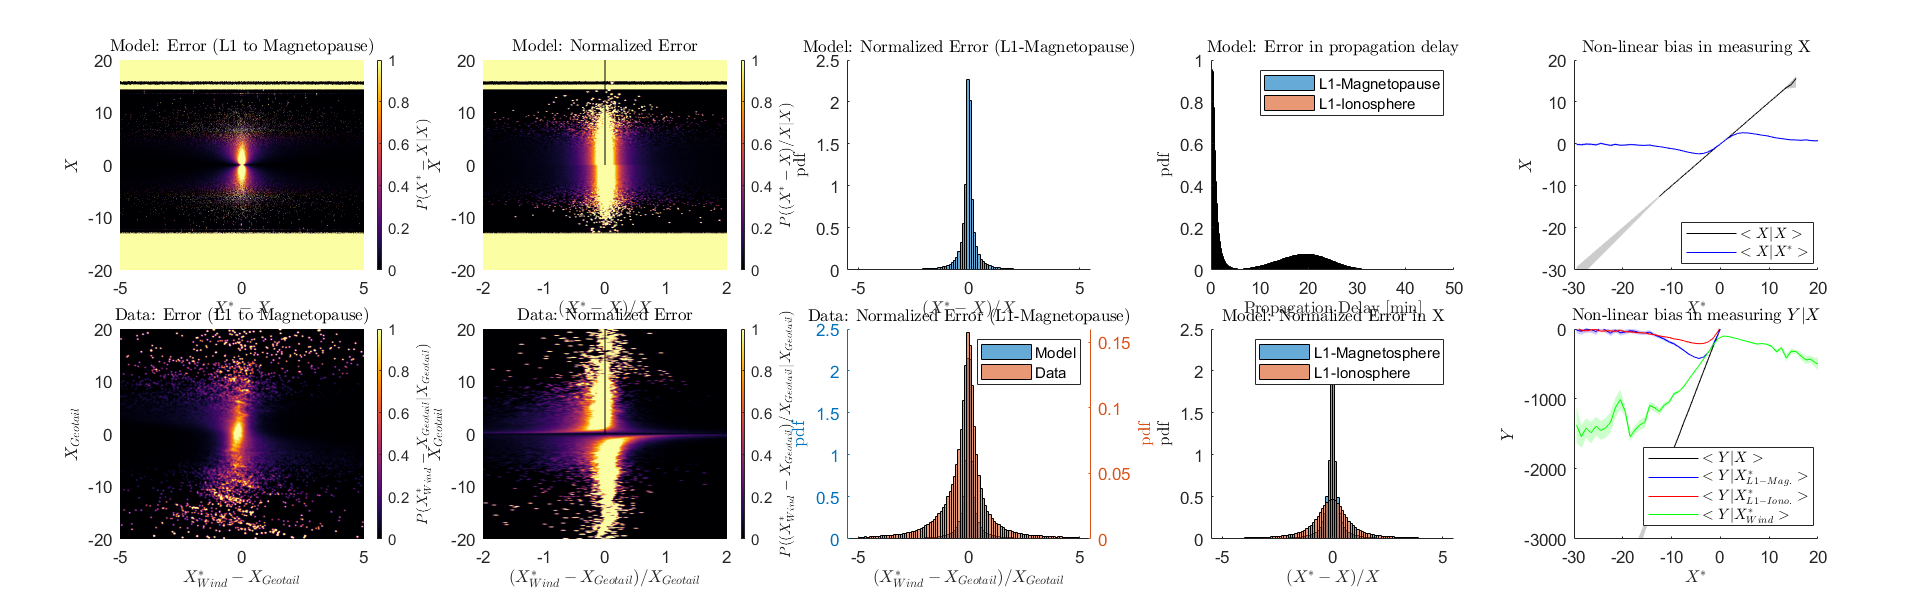

set(0,'defaulttextInterpreter','latex');
h=figure;
resize_figure(h,150,480);
p = panel();
p.pack(2,5);
p.select('all');
p.marginleft = 30;
p.marginright = 25;
p.margintop = 15;
p(2).de.margintop = 20;
p(1).de.marginbottom = 15;

% Plotting Conditional Probability of error given X, Model
p(1,1).select();
colormap(inferno);
plot_2D_error(XPegX, YPegX, PegX,'$P(X^*-X|X)$');
caxis([0,1]);
xlabel('$X^*-X$','Interpreter','latex');
ylabel('$X$');
title('Model: Error (L1 to Magnetopause)');

% Plotting Conditional Probability of error given X, Data
p(2,1).select();
colormap(inferno);
plot_2D_error(XPeSgXS, YPeSgXS, PeSgXS,'$P(X^*_{Wind}-X_{Geotail}|X_{Geotail})$');
caxis([0,1]);
xlabel('$X^*_{Wind}-X_{Geotail}$','Interpreter','latex');
ylabel('$X_{Geotail}$');
title('Data: Error (L1 to Magnetopause)');


% Plotting Conditional Probability of normalized error given X, Model
p(1,2).select();
colormap(inferno);
plot_2D_error(XPeNgX, YPeNgX, PeNgX,'$P((X^*-X)/X|X)$');
caxis([0,1]);
xlabel('$(X^*-X)/X$','Interpreter','latex');
ylabel('$X$');
title('Model: Normalized Error');
hold on;
plot(repmat(0,100),linspace(0,20,100),'k');
xlim([-2,2]);

% Plotting Conditional Probability of normalized error given X, Data
p(2,2).select();
colormap(inferno);
plot_2D_error(XPeNSgXS, YPeNSgXS, PeNSgXS,'$P((X^*_{Wind}-X_{Geotail})/X_{Geotail}|X_{Geotail})$');
caxis([0,1]);
xlabel('$(X^*_{Wind}-X_{Geotail})/X_{Geotail}$','Interpreter','latex');
ylabel('$X_{Geotail}$');
title('Data: Normalized Error');
hold on;
plot(repmat(0,100),linspace(0,20,100),'k');
xlim([-2,2]);

% Normalized error pdf, Model (L1-magnetopause)
p(1,3).select();
eBins = -5:0.1:5;
histogram(U,eBins,'Normalization','pdf');
xlabel('$(X^*-X)/X$','Interpreter','latex');
ylabel('pdf');
title('Model: Normalized Error (L1-Magnetopause)');

% Comparing this with data
%?? Here there is a problem with magnitude of pdfs not matching,  but the
% shape does
p(2,3).select();
eBins = -5:0.1:5;
yyaxis left
histogram(eNorm,eBins,'Normalization','pdf');
ylabel('pdf');
hold on;
yyaxis right
histogram(eNormS,eBins,'Normalization','pdf');
legend('Model','Data');
xlabel('$(X^*_{Wind}-X_{Geotail})/X_{Geotail}$','Interpreter','latex');
ylabel('pdf');
title('Data: Normalized Error (L1-Magnetopause)');

%
p(1,4).select();
histogram(time - time_L1_N,'Normalization','pdf');
hold on;
histogram(time - time_L1_I,'Normalization','pdf');
ylabel('pdf');
xlabel('Propagation Delay [min]');
title('Model: Error in propagation delay');
legend('L1-Magnetopause','L1-Ionosphere');
xlim([0,50]);

p(2,4).select();
histogram(eNorm,eBins,'Normalization','pdf');
hold on;
histogram(eNormT,eBins,'Normalization','pdf');
legend('L1-Magnetosphere','L1-Ionosphere');
title('Model: Normalized Error in X');
xlabel('$(X^*-X)/X$');
ylabel('pdf');

p(1,5).select();
p1 = plot_curve(EXgX,'k');
hold on;
p2 = plot_curve(EXgW,'b');
xlabel('$X^*$');
ylabel('$X$');
legend([p1,p2],{'$<X|X>$','$<X|X^*>$'},'Location','best','Interpreter','latex');
ylim([-30,20]);
xlim([-30,20]);
title('Non-linear bias in measuring X');

p(2,5).select();
p1 = plot_curve(EYgX,'k');
hold on;
p2 = plot_curve(EYgW,'b');
hold on;
p3 = plot_curve(EYgWT,'r');
hold on;
p4 = plot_curve(EYSgXm,'g');
xlabel('$X^*$');
ylabel('$Y$');
legend([p1,p2,p3,p4],{'$<Y|X>$','$<Y|X_{L1-Mag.}^*>$','$<Y|X_{L1-Iono.}^*>$','$<Y|X_{Wind}^*>$'},'Location','best','Interpreter','latex');
ylim([-3000,0]);
xlim([-30,20]);
title('Non-linear bias in measuring $Y|X$');

## Plotting Inputs

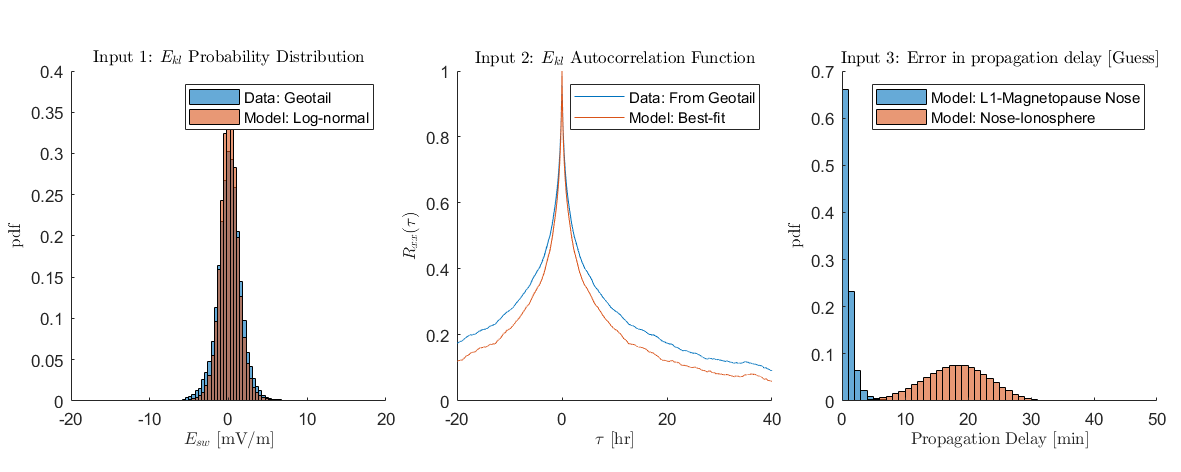

h1 = figure;
resize_figure(h1,100,250);
p = panel();
p.pack(1,3);
XBins = linspace(-20,20,100);
p.select('all');
% p.marginleft = 30;
% p.marginright = 25;
p.margintop = 15;

filter.geo = ((geotail.noseYGSE-geotail.YGSE).^2 + (geotail.noseZGSE-geotail.ZGSE).^2).^0.5 < 7;
p(1,1).select();
histogram(XS(filter.geo),XBins,'Normalization','pdf');
hold on;
histogram(X,XBins,'Normalization','pdf');
set(gca,'XScale','linear');
legend('Data: Geotail','Model: Log-normal');
title('Input 1: $E_{kl}$ Probability Distribution');
xlabel('$E_{sw}$ [mV/m]');
ylabel('pdf');
xlim([-20 20]);
  
p(1,2).select();
plot(fftshift(lag/60),fftshift(Rm));
hold on;
plot(fftshift(lageX/60),fftshift(mean(RArrayX./RArrayX(:,1))));
legend('Data: From Geotail','Model: Best-fit');
ylim([0,1]);
xlim([-20,40]);
ylabel('$R_{xx}(\tau)$');
xlabel('$\tau$ [hr]');
title('Input 2: $E_{kl}$ Autocorrelation Function');

p(1,3).select();
tbin = 0:1:50;
histogram(terr_L1_N,tbin,'Normalization','pdf');
hold on;
histogram(terr_N_I,tbin,'Normalization','pdf');
legend('Model: L1-Magnetopause Nose','Model: Nose-Ionosphere')
xlim([0,50]);
xlabel('Propagation Delay [min]');
ylabel('pdf');
title('Input 3: Error in propagation delay [Guess]');

## Insights

1: Geotail might not be the true value (?) There is uncertainty in the geotail measurement, that alters the P(Y|X*)

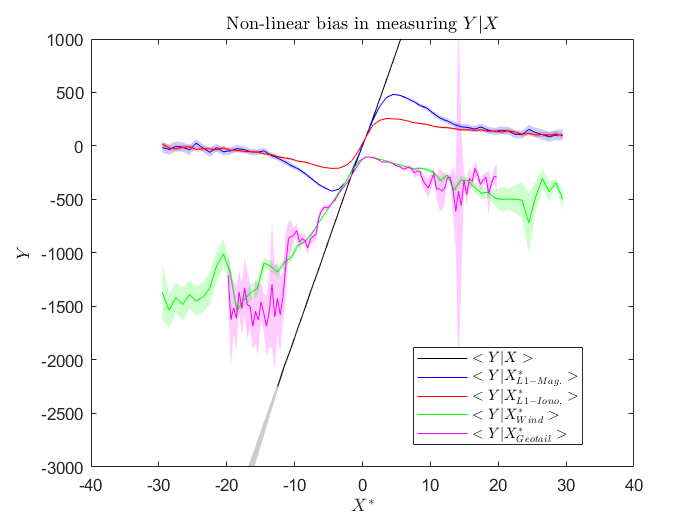

filter.geo = ((geotail.noseYGSE-geotail.YGSE).^2 + (geotail.noseZGSE-geotail.ZGSE).^2).^0.5 < 20;
EYSgXS = create_curve(XS(filter.geo),YS(filter.geo),XBins);
figure;
p1 = plot_curve(EYgX,'k');
hold on;
p2 = plot_curve(EYgW,'b');
hold on;
p3 = plot_curve(EYgWT,'r');
hold on;
p4 = plot_curve(EYSgXm,'g');
hold on;
p5 = plot_curve(EYSgXS,'m');
xlabel('$X^*$');
ylabel('$Y$');
legend([p1,p2,p3,p4,p5],{'$<Y|X>$','$<Y|X_{L1-Mag.}^*>$',...
    '$<Y|X_{L1-Iono.}^*>$','$<Y|X_{Wind}^*>$','$<Y|X_{Geotail}^*>$'},...
'Location','best','Interpreter','latex');
ylim([-3000,1000]);
xlim([-40,40]);
title('Non-linear bias in measuring $Y|X$');

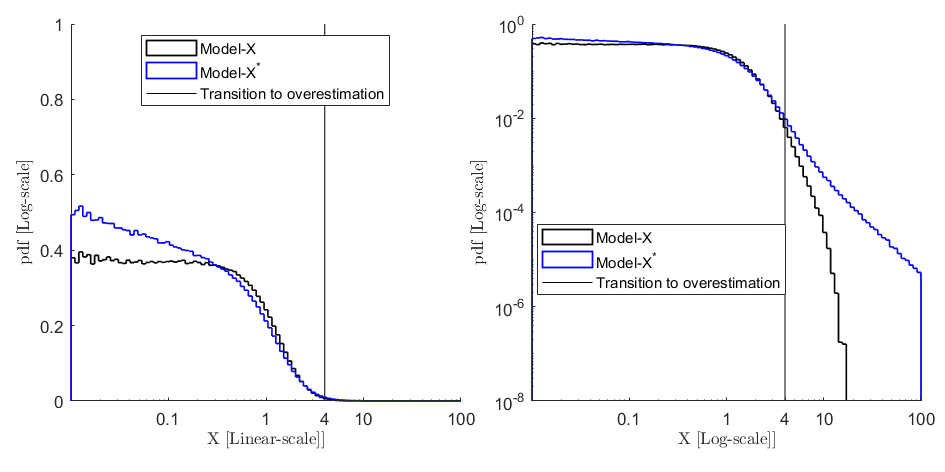


% 2: Probability distribution is changed, overestimation beyond a threshold
h3 = figure; 
resize_figure(h3,100,200);
p = panel();
p.pack(1,2);
p.select('all');

XBinsLog = logspace(-2,2,100);

p(1,1).select();
histogram(X,XBinsLog,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor','k');
hold on;
histogram(W, XBinsLog, 'Normalization', 'pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor','b');
set(gca,'XScale','log','Yscale','linear','XTick',[0.1,1,4,10,100]);
hold on;
plot(repmat(4,100,1),linspace(0,1,100),'k');
legend('Model-X','Model-X^*','Transition to overestimation','Location','best');
xlabel('X [Linear-scale]]');
ylabel('pdf [Log-scale]');

p(1,2).select();
histogram(X,XBinsLog,'Normalization','pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor','k');
hold on;
histogram(W, XBinsLog, 'Normalization', 'pdf','DisplayStyle','stairs','LineWidth',1,'EdgeColor','b');
hold on;
plot(repmat(4,100,1),linspace(10^-8,1,100),'k');
legend('Model-X','Model-X^*','Transition to overestimation','Location','best');
set(gca,'XScale','log','Yscale','log','XTick',[0.1,1,4,10,100]);
xlabel('X [Log-scale]]');
ylabel('pdf [Log-scale]');


% 3: Probability distribution scrambling
nBins = 100;
XBins = linspace(-20,20,nBins);
[edges1, value1] = create_segmented_pdfs(X,X,XBins,XBins);
cf = colormap(get_colormap3('k','w','b',nBins));

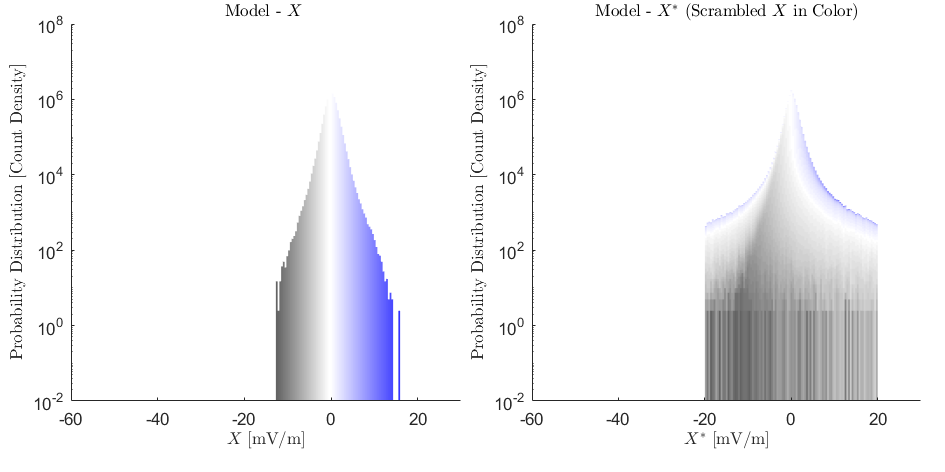

% cf = inferno(nBins);

h4 = figure; 
resize_figure(h4,100,200);
p = panel();
p.pack(1,2);
p.select('all');

p(1,1).select();
bar((edges1),value1','BarLayout','stacked','BarWidth',1,'EdgeColor','none');
set(gca,'XScale','linear','YScale','log');
colororder(cf);
xlabel('$X$ [mV/m]');
ylabel('Probability Distribution [Count Density]');
title('Model - $X$ ');
xlim([-60,30]);
ylim([10^-2,10^8]);


p(1,2).select();
[edges2, value2] = create_segmented_pdfs(X,W,XBins,XBins);
bar((edges2),value2','BarLayout','stacked','BarWidth',1,'EdgeColor','none');
set(gca,'XScale','linear','YScale','log');
colororder(cf);
ylim([10^-2,10^8]);
xlim([-60,30]);
xlabel('$X^*$ [mV/m]');
ylabel('Probability Distribution [Count Density]');
title('Model - $X^*$ (Scrambled $X$ in Color)');


% 4: Conditional probabilities are affected

XBins = -30:1:20;
[PWgX,XPWgX,YPWgX] = conditional_pdf(W(:),X(:),-30:1:20,-30:1:20);
[PXgW,XPXgW,YPXgW] = conditional_pdf(X(:),W(:),-30:1:20,-30:1:20);
EWgX = create_curve(X(:),W(:),XBins);


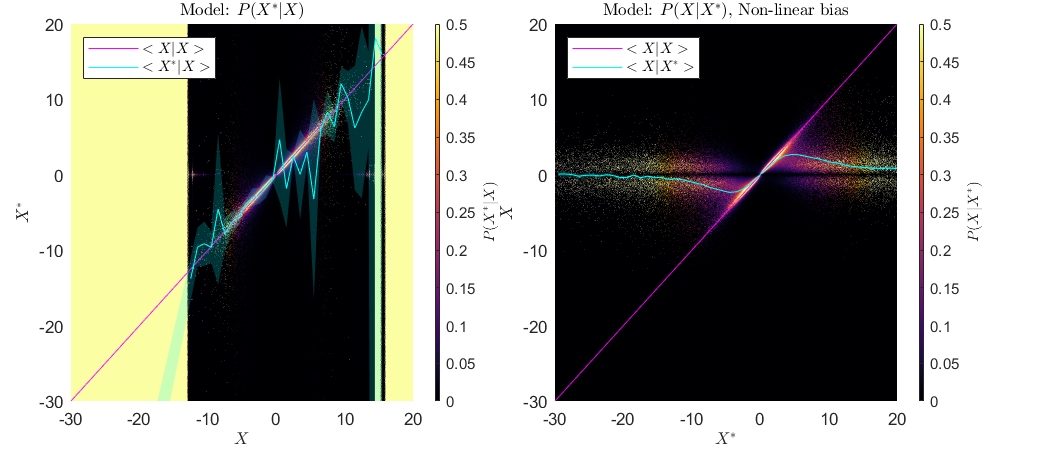


h5 = figure; 
resize_figure(h5,100,220);
p = panel();
p.pack(1,2);
p.marginright=30;
p.select('all');

XBin = -30:20; 

p(1,1).select();
colormap(inferno);
plot_2D_error(XPWgX, YPWgX, PWgX','$P(X^*|X)$');
caxis([0,0.5]);
ylabel('$X^*$','Interpreter','latex');
xlabel('$X$');
title('Model: $P(X^*|X)$');
hold on;
p1 = plot(XBin,XBin,'m');
hold on;
p2 = plot_curve(EWgX,'c');
xlim([-30,20]);
ylim([-30,20]);
legend([p1,p2],{'$<X|X>$','$<X^*|X>$'},'Location','northwest','Interpreter','latex');


p(1,2).select();
colormap(inferno);
plot_2D_error(XPXgW, YPXgW, PXgW','$P(X|X^*)$');
caxis([0,0.5]);
ylabel('$X$','Interpreter','latex');
xlabel('$X^*$');
hold on;
p3 = plot(XBin,XBin,'m');
hold on;
p4 = plot_curve(EXgW,'c');
xlim([-30,20]);
ylim([-30,20]);
legend([p3,p4],{'$<X|X>$','$<X|X^*>$'},'Location','northwest','Interpreter','latex');
title('Model: $P(X|X^*)$, Non-linear bias');

## Rough

figure;
xB = 0:0.5:30;
histogram((random('Half Normal',0,6,nSamples,nEnsembles))',xB,'Normalization',"pdf");
hold on;
s = 3;
m = 2.5;
histogram((random('Lognormal',log(s.^2./(s.^2+m.^2).^0.5),sqrt(log(1+s.^2./m.^2)),nSamples,nEnsembles))',xB,'Normalization',"pdf");
xlim([0,20]);
ylim([0,0.2]);

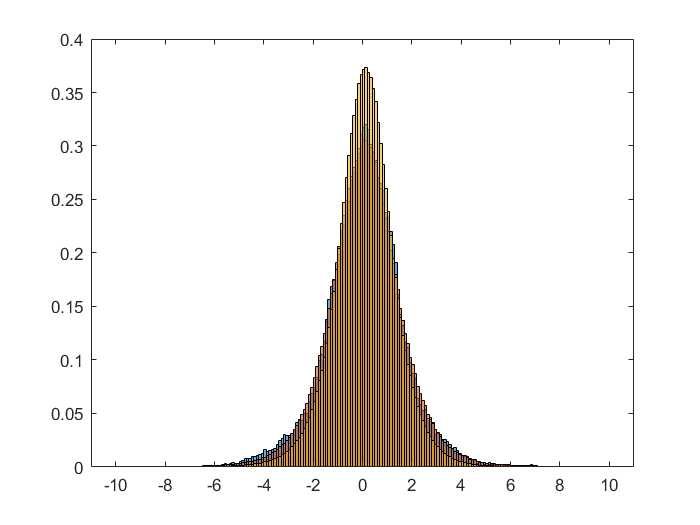

X = MvtRand( repmat(0.104846, nSamples, 1) , 5.41353 , repmat(10, nSamples, 1), nEnsembles , RmMatrix);
filter.geo = ((geotail.noseYGSE-geotail.YGSE).^2 + (geotail.noseZGSE-geotail.ZGSE).^2).^0.5 < 5;
figure;
histogram(XS(filter.geo),-10:0.1:10,'Normalization','pdf');
tfit=fitdist(XS(filter.geo),'tLocationScale');
XXX1 = random(tfit,nSamples,nEnsemble);
hold on;
histogram(XXX1,-10:0.1:10,'Normalization','pdf');
hold on;
histogram(X,-10:0.1:10,'Normalization','pdf');

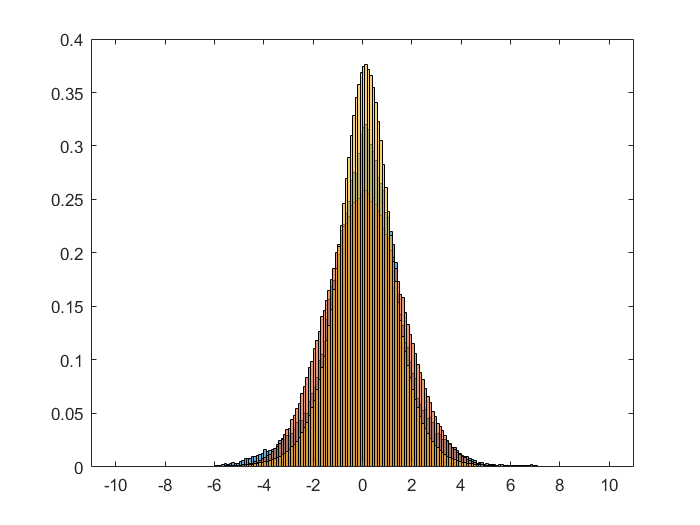

X = MvtRand( repmat(0.104846, nSamples, 1) , 5.41353 , repmat(1.25289, nSamples, 1), nEnsembles , RmMatrix);
filter.geo = ((geotail.noseYGSE-geotail.YGSE).^2 + (geotail.noseZGSE-geotail.ZGSE).^2).^0.5 < 5;
figure;
histogram(XS(filter.geo),-10:0.1:10,'Normalization','pdf');
tfit=fitdist(XS(filter.geo),'Normal');
XXX1 = random(tfit,nSamples,nEnsemble);
hold on;
histogram(XXX1,-10:0.1:10,'Normalization','pdf');
hold on;
histogram(X,-10:0.1:10,'Normalization','pdf');

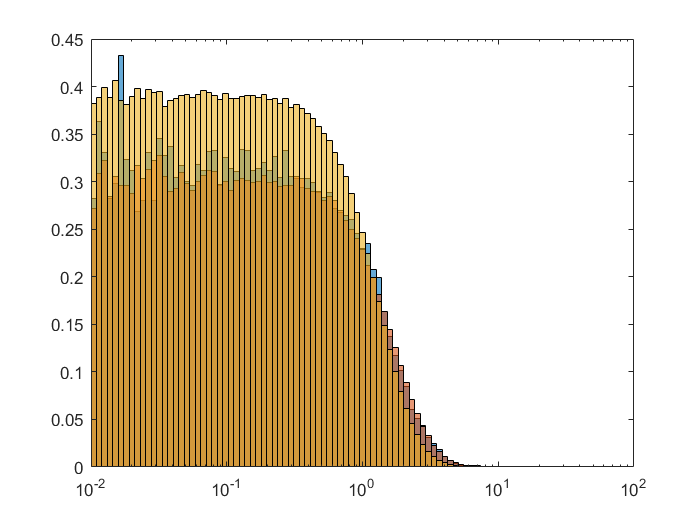

filter.geo = ((geotail.noseYGSE-geotail.YGSE).^2 + (geotail.noseZGSE-geotail.ZGSE).^2).^0.5 < 5;
XXXBin = logspace(-2,2,100);
figure;
histogram(XS(filter.geo),XXXBin,'Normalization','pdf');
tfit=fitdist(XS(filter.geo),'tLocationScale');
XXX1 = random(tfit,nSamples,nEnsemble);
hold on;
histogram(XXX1,XXXBin,'Normalization','pdf');
hold on;
histogram(X,XXXBin,'Normalization','pdf');
xlim([10^-2,10^2]);
set(gca,'XScale','log');

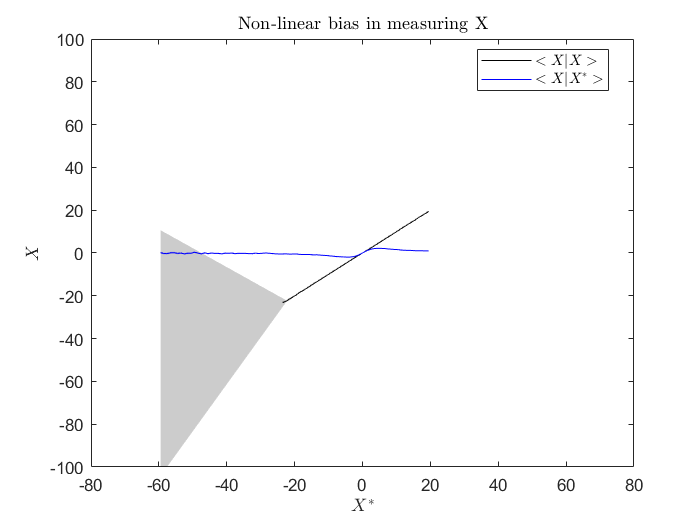

figure;
p1 = plot_curve(EXgX,'k');
hold on;
p2 = plot_curve(EXgW,'b');
xlabel('$X^*$');
ylabel('$X$');
legend([p1,p2],{'$<X|X>$','$<X|X^*>$'},'Location','best','Interpreter','latex');
ylim([-100,100]);
xlim([-80,80]);
title('Non-linear bias in measuring X');

## Functions

function [edges, value] = create_segmented_pdfs(X,Y,XBins,XSegments,normalizationStr)

if nargin<5
    normalizationStr = 'countdensity';
end

value = zeros(length(XSegments),length(XBins)-1);
for i=1:1:length(XSegments)
    if i==1
        [value(i,:),edges] = histcounts(Y(X<=XSegments(i)),XBins,'Normalization',normalizationStr);
%         edges = hh.BinEdges(2:end) - (hh.BinEdges(2)-hh.BinEdges(1))/2;
        edges = edges(2:end) - (edges(2)-edges(1))/2;
%         edges = edges(1:end-1);
    elseif i>1 && i < length(XSegments)
        value(i,:) = histcounts(Y(X>XSegments(i-1) & X<=XSegments(i)),XBins,'Normalization',normalizationStr);
    else
       value(i,:) = histcounts(Y(X>=XSegments(i-1)),XBins,'Normalization',normalizationStr);
    end
    
%     value(i,:) = hh.Values; 
end

end


function p = plot_curve(curve, color)

CI1 = interp_nans(curve.CI);
p=plot(curve.XBins, curve.YgX,color);
hold on;
plot_ci(curve.XBins,CI1,color,0.2);
end

function plot_ci(x,ci,color,alpha)
    hold on;
    X2 = [x, fliplr(x)];
    inBetween = [ci(:,1)', fliplr(ci(:,2)')];
    fill(X2,inBetween,color,'LineStyle','none','FaceAlpha',alpha);
end

function plot_2D_error(Y,X,P,yLabel)
    p = pcolor(Y,X,P);
    set(p,'EdgeColor','none');
    colorbar_thin('YLabel',yLabel);
end

function curve = create_curve(X, Y, Ei)

if nargin<3
    Ei = 100;
end
Y = Y(:);
Y(Y==999999)=nan;

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

[xindx, E] = discretize(X(:),Ei);

for i = 1:max(xindx)
    curve.YgX(i) = nanmean(Y(xindx==i));
    curve.stdYgX(i) = nanstd(Y(xindx==i));
    curve.NSamples(i) = sum(xindx==i & ~isnan(Y));
    curve.SEM(i) = nanstd(Y(xindx==i))./sqrt(curve.NSamples(i));
    curve.ts(i,:) = tinv([0.025 0.975],curve.NSamples(i)-1);
    curve.CI(i,:) = curve.YgX(i) + curve.ts(i,:)*curve.SEM(i);
    curve.XBins(i) = 0.5*(E(i)+E(i+1));
end

curve.E = E; 

end

function [fXgY,XX,YY] = conditional_pdf(X, Y, gridx, gridy)

X1 = X(~isnan(X) & ~isnan(Y));
Y1 = Y(~isnan(X) & ~isnan(Y));
X = X1;
Y = Y1;

sz = 2^10;
Y = Y(:);
Y(Y==999999)=nan;

[bandwidth,fXY,XX,YY]=kde2d([X,Y],sz,[min(gridx),min(gridy)],[max(gridx),max(gridy)]);
[fY, YY1] = ksdensity(Y,YY(:,1));

fXgY = fXY./repmat(fY,1,sz);

% [XX, YY] = meshgrid(gridx,gridy);
% 
% [fxy, yii] = ksdensity([X,Y],[XX(:),YY(:)]);
% Fxy = scatteredInterpolant(yii(:,1),yii(:,2),fxy);
% 
% [fy, yi] = ksdensity(Y,gridy);
% Fy = griddedInterpolant(yi,fy);
% 
% cpdf = Fxy(XX,YY)./(Fy(gridy)')./(sum((Fxy(XX,YY)./(Fy(gridy)')),2));

end


function [M, nSample, nEnsemble]= split_series(series,sampleSize,MaxNoOfMissingValues)
    if nargin<3
        MaxNoOfMissingValues=1000;
    end
        
    series = padarray(series,sampleSize-mod(length(series),sampleSize),'post');
    L = length(series); 
    M0 = reshape(series,sampleSize,[])';
    indx=sum(isnan(M0),2)>MaxNoOfMissingValues;
    l = 1:1:size(M0,1);
    k=1;
    for i=l(~indx)
        M(k,:) = M0(i,:);
        k=k+1;
    end
    nSample = size(M,2);
    nEnsemble = size(M,1);
    
    M = interp_nans(M')';
    
%     M = M-mean(M,2);
end

function [RArray,lag]=find_correlation(M,nSample,nEnsemble,sampleTime)
    dt = sampleTime;
    lag = fftshift(-nSample:1:nSample-1)'.*dt;
    xCell = mat2cell(M, ones(1,nEnsemble),nSample);
    [RArray] = cellfun(@(x) xcorr(x,'unbiased'),xCell,'UniformOutput',false);
    RArray = cell2mat(RArray);
    RArray(:,2:end+1) = RArray(:,1:end);
    RArray(:,1)=RArray(:,2);
    RArray = ifftshift(RArray);
end


function omni = extract_omni_data(omniFile)
    
    %Time
    time = unixtime2matlab(h5read(omniFile,'/Time'));
    omni.time = time; 
    
        % Auroral electrojet indices
    SML = h5read(omniFile,'/Indices/SML');
    omni.Fsml = griddedInterpolant(time,SML);
    
    SMU = h5read(omniFile,'/Indices/SMU');
    omni.Fsmu = griddedInterpolant(time,SMU);
    
    AL = h5read(omniFile,'/Indices/AL');
    AL(AL==99999)=nan;
    omni.FAL = griddedInterpolant(time, AL);
    
    AU = h5read(omniFile,'/Indices/AU');
    AU(AU==99999)=nan;
    omni.FAU = griddedInterpolant(time, AU);
    
    symH = h5read(omniFile,'/Indices/SYM_H');
    omni.FsymH = griddedInterpolant(time, symH);
    % Solar wind
    
        % IMF Bz
    BzGSM = h5read(omniFile,'/BField/BzGSM');
    omni.FBz = griddedInterpolant(time,BzGSM);
    
        % IMF By
    ByGSM = h5read(omniFile,'/BField/ByGSM');
    omni.FBy = griddedInterpolant(time,ByGSM);
    
    
        % IMF B_T (Tangential to to GSM_x)
    BzGSM(BzGSM==0) = 0.0001;
    B_T = (ByGSM.^2 + BzGSM.^2).^0.5;
    
        % IMF Clock angle
    theta_kl = wrapTo2Pi(atan2(B_T,BzGSM));
        
        
        % Velocity
    velocity = h5read(omniFile,'/Velocity/V');
    omni.Fv = griddedInterpolant(time,velocity);
    
    
    % Solarwind - Magnetosphere Coupling
    l_0 = 7*(6371*10^3);
    
    E_kl = velocity.*B_T.*(sin(theta_kl/2)).^2; %Km nT/s
    % The “geoeffective” (or “merging”) electric field [Kan and Lee, 1979]
    omni.Fekl = griddedInterpolant(time,E_kl);  
    
    E_sw = velocity.*B_T;
    omni.Fesw = griddedInterpolant(time,E_sw);  
    
    
end

function T1 = extract_data(loadFile)
 
        format = '%4f %4f %3f %3f %4f %4f %4.1f %6f %6.2f %6.2f %6.2f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %7f %6.2f %8.2f %8.2f %4f %8.1f %8.1f %8.1f %8.1f %7.2f %9.0f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %8.2f %7f %7f';
        tempData = load_ascii_files(loadFile, format, 0);
        T.datetime = datetime(tempData{1},1,tempData{2},tempData{3},tempData{4},zeros(size(tempData{4})));
        T.timeshift = tempData{8}; T.timeshift(T.timeshift==999999) = nan;
        T.BxGSM = tempData{13};  T.BxGSM(T.BxGSM > 9999) = nan;
        T.ByGSM = tempData{16}; T.ByGSM(T.ByGSM > 9999) = nan;
        T.BzGSM = tempData{17}; T.BzGSM(T.BzGSM > 9999) = nan;
        T.velocity = tempData{23}; T.velocity(T.velocity > 99999) = nan;
        T.B_T = (T.ByGSM.^2 + T.BzGSM.^2).^0.5;
        T.theta_kl = wrapTo2Pi(atan2(T.B_T,T.BzGSM));
        T.E_kl = T.velocity.*T.B_T.*(sin(T.theta_kl/2)).^2;
        T.E_sw = T.velocity.*T.BzGSM;
        T.XGSE = tempData{29}; T.XGSE(T.XGSE > 9999) = nan;
        T.YGSE = tempData{30}; T.YGSE(T.YGSE > 9999) = nan;
        T.ZGSE = tempData{31}; T.ZGSE(T.ZGSE > 9999) = nan;
        T.noseXGSE = tempData{32}; T.noseXGSE(T.noseXGSE > 9999) = nan;
        T.noseYGSE = tempData{33}; T.noseYGSE(T.noseYGSE > 9999) = nan;
        T.noseZGSE = tempData{34}; T.noseZGSE(T.noseZGSE > 9999) = nan;
        T.distance = sqrt((T.XGSE-T.noseXGSE).^2 + (T.YGSE-T.noseYGSE).^2 + (T.ZGSE-T.noseZGSE).^2);
        T1 = struct2table(T);
end

function T = extract_set_of_data(loadFolder,satellite)
    fileStr = get_files_in_folder(loadFolder,[satellite,'_min_b*.txt']);
    for i=1:1:length(fileStr)
        T1 = extract_data([loadFolder,fileStr{i}]);
        if i==1
            T=T1;
        else
            T = [T;T1];
        end
    end
end

## External Functions

## Stochastic process from Log-normal distribution

function y = MvLogNRand( Mu , Sigma , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end
if numel(Mu) ~= numel(Sigma)
    error('Mu and Sigma must have the same number of elements')
end
% Force column vectors
Mu     = Mu(:);
Sigma  = Sigma(:);
% Calculate the covariance structure
sigma_down = repmat( Sigma' , numel(Sigma), 1            );
sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
covv = log( CorrMat .* sqrt(exp(sigma_down.^2)-1) .* ...
                       sqrt(exp(sigma_acrs.^2)-1) + 1 );
% The Simulation
y = exp( mvnrnd( Mu , covv , Simulations ));
end

function y = MvNRand( Mu , Sigma , Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end
if numel(Mu) ~= numel(Sigma)
    error('Mu and Sigma must have the same number of elements')
end
% Force column vectors
Mu     = Mu(:);
Sigma  = Sigma(:);
% Calculate the covariance structure
% sigma_down = repmat( Sigma' , numel(Sigma), 1            );
% sigma_acrs = repmat( Sigma  , 1           , numel(Sigma) );
D = diag(Sigma);
covv = ( D*CorrMat*D );
% The Simulation
y = mvnrnd( Mu , covv , Simulations );
end

function y = MvtRand( Mu , Nu , Sigma, Simulations , CorrMat )
%MVLOGNRAND MultiVariant Lognormal random numbers with correlation
%
%   Mu: The Lognormal parameter Mu  (can be column or row vector)
%
%   Sigma: The Lognormal parameter Sigma (can be column or row vector)
%
%   Simulations:  The Number of simulations to run (scalar)
%
%   CorrMat:  OPTIONAL A square matrix with the number of rows and columns
%   equal to the number of elements in Mu/Sigma.  Each element on the
%   diagonal is equal to one, with the off diagonal cells equal to the
%   correlation of the marginal Lognormal distributions. If not specified,
%   then assume zero correlation.
%
%   To check the simulation run corrcoef(Y) and that should be the same as
%   your CorrMat.
%
%   REQUIRES THE STATISTICS TOOLBOX
%
%   Example:
%   Mu    = [ 11 12 13 ];
%   Sigma = [ .1 .3 .5 ];
%   Simulations = 1e6;
%   CorrMat = [1 .2 .4 ; .2 1 .5 ; .4  .5 1];
%   y = MvLogNRand( Mu , Sigma , Simulations , CorrMat );
%
%   corrcoef(y)
%   ans =
%            1      0.19927      0.40156
%      0.19927            1      0.50008
%      0.40156      0.50008            1
%
%   CorrMat =
%               1          0.2          0.4
%             0.2            1          0.5
%             0.4          0.5            1
%
%   For more information see: Aggregration of Correlated Risk Portfolios:
%   Models and Algorithms; Shaun S. Wang, Phd.  Casualty Actuarial Society
%   Proceedings Volume LXXXV www.casact.org
%
%   Author: Stephen Lienhard
% Error checking
if nargin < 3
    error('Must have at least 3 input arguements')
end
if numel(Simulations) ~= 1 || Simulations < 0
    error('The number of simulations must be greater then zero and a scalar')
end
if nargin == 3
    CorrMat = eye(numel(Mu));
elseif size(CorrMat,1) ~= size(CorrMat,2)
    error('The correlation matrix must have the same number of rows as columns')
end
if numel(Mu) ~= numel(Sigma)
    error('Mu and Sigma must have the same number of elements')
end
% Force column vectors
Mu     = Mu(:);
% Calculate the covariance structure
% The Simulation
% y = Mu' + Sigma'.*mvtrnd(CorrMat, Nu, Simulations);
y = Mu' + mvtrnd(CorrMat, Nu, Simulations);
end

## KDE2D

function [bandwidth,density,X,Y]=kde2d(data,n,MIN_XY,MAX_XY)
% fast and accurate state-of-the-art
% bivariate kernel density estimator
% with diagonal bandwidth matrix.
% The kernel is assumed to be Gaussian.
% The two bandwidth parameters are
% chosen optimally without ever
% using/assuming a parametric model for the data or any "rules of thumb".
% Unlike many other procedures, this one
% is immune to accuracy failures in the estimation of
% multimodal densities with widely separated modes (see examples).
% INPUTS: data - an N by 2 array with continuous data
%            n - size of the n by n grid over which the density is computed
%                n has to be a power of 2, otherwise n=2^ceil(log2(n));
%                the default value is 2^8;
% MIN_XY,MAX_XY- limits of the bounding box over which the density is computed;
%                the format is:
%                MIN_XY=[lower_Xlim,lower_Ylim]
%                MAX_XY=[upper_Xlim,upper_Ylim].
%                The dafault limits are computed as:
%                MAX=max(data,[],1); MIN=min(data,[],1); Range=MAX-MIN;
%                MAX_XY=MAX+Range/4; MIN_XY=MIN-Range/4;
% OUTPUT: bandwidth - a row vector with the two optimal
%                     bandwidths for a bivaroate Gaussian kernel;
%                     the format is:
%                     bandwidth=[bandwidth_X, bandwidth_Y];
%          density  - an n by n matrix containing the density values over the n by n grid;
%                     density is not computed unless the function is asked for such an output;
%              X,Y  - the meshgrid over which the variable "density" has been computed;
%                     the intended usage is as follows:
%                     surf(X,Y,density)
% Example (simple Gaussian mixture)
% clear all
%   % generate a Gaussian mixture with distant modes
%   data=[randn(500,2);
%       randn(500,1)+3.5, randn(500,1);];
%   % call the routine
%     [bandwidth,density,X,Y]=kde2d(data);
%   % plot the data and the density estimate
%     contour3(X,Y,density,50), hold on
%     plot(data(:,1),data(:,2),'r.','MarkerSize',5)
%
% Example (Gaussian mixture with distant modes):
%
% clear all
%  % generate a Gaussian mixture with distant modes
%  data=[randn(100,1), randn(100,1)/4;
%      randn(100,1)+18, randn(100,1);
%      randn(100,1)+15, randn(100,1)/2-18;];
%  % call the routine
%    [bandwidth,density,X,Y]=kde2d(data);
%  % plot the data and the density estimate
%  surf(X,Y,density,'LineStyle','none'), view([0,60])
%  colormap hot, hold on, alpha(.8)
%  set(gca, 'color', 'blue');
%  plot(data(:,1),data(:,2),'w.','MarkerSize',5)
%
% Example (Sinusoidal density):
%
% clear all
%   X=rand(1000,1); Y=sin(X*10*pi)+randn(size(X))/3; data=[X,Y];
%  % apply routine
%  [bandwidth,density,X,Y]=kde2d(data);
%  % plot the data and the density estimate
%  surf(X,Y,density,'LineStyle','none'), view([0,70])
%  colormap hot, hold on, alpha(.8)
%  set(gca, 'color', 'blue');
%  plot(data(:,1),data(:,2),'w.','MarkerSize',5)
%
%  Reference:
% Kernel density estimation via diffusion
% Z. I. Botev, J. F. Grotowski, and D. P. Kroese (2010)
% Annals of Statistics, Volume 38, Number 5, pages 2916-2957.
global N A2 I
if nargin<2
    n=2^8;
end
n=2^ceil(log2(n)); % round up n to the next power of 2;
N=size(data,1);
if nargin<3
    MAX=max(data,[],1); MIN=min(data,[],1); Range=MAX-MIN;
    MAX_XY=MAX+Range/2; MIN_XY=MIN-Range/2;
end
scaling=MAX_XY-MIN_XY;
if N<=size(data,2)
    error('data has to be an N by 2 array where each row represents a two dimensional observation')
end
transformed_data=(data-repmat(MIN_XY,N,1))./repmat(scaling,N,1);
%bin the data uniformly using regular grid;
initial_data=ndhist(transformed_data,n);
% discrete cosine transform of initial data
a= dct2d(initial_data);
% now compute the optimal bandwidth^2
  I=(0:n-1).^2; A2=a.^2;
 t_star=root(@(t)(t-evolve(t)),N);
p_02=func([0,2],t_star);p_20=func([2,0],t_star); p_11=func([1,1],t_star);
t_y=(p_02^(3/4)/(4*pi*N*p_20^(3/4)*(p_11+sqrt(p_20*p_02))))^(1/3);
t_x=(p_20^(3/4)/(4*pi*N*p_02^(3/4)*(p_11+sqrt(p_20*p_02))))^(1/3);
% smooth the discrete cosine transform of initial data using t_star
a_t=exp(-(0:n-1)'.^2*pi^2*t_x/2)*exp(-(0:n-1).^2*pi^2*t_y/2).*a; 
% now apply the inverse discrete cosine transform
if nargout>1
    density=idct2d(a_t)*(numel(a_t)/prod(scaling));
	density(density<0)=eps; % remove any negative density values
    [X,Y]=meshgrid(MIN_XY(1):scaling(1)/(n-1):MAX_XY(1),MIN_XY(2):scaling(2)/(n-1):MAX_XY(2));
end
bandwidth=sqrt([t_x,t_y]).*scaling; 
end
%#######################################
function  [out,time]=evolve(t)
global N
Sum_func = func([0,2],t) + func([2,0],t) + 2*func([1,1],t);
time=(2*pi*N*Sum_func)^(-1/3);
out=(t-time)/time;
end
%#######################################
function out=func(s,t)
global N
if sum(s)<=4
    Sum_func=func([s(1)+1,s(2)],t)+func([s(1),s(2)+1],t); const=(1+1/2^(sum(s)+1))/3;
    time=(-2*const*K(s(1))*K(s(2))/N/Sum_func)^(1/(2+sum(s)));
    out=psi(s,time);
else
    out=psi(s,t);
end
end
%#######################################
function out=psi(s,Time)
global I A2
% s is a vector
w=exp(-I*pi^2*Time).*[1,.5*ones(1,length(I)-1)];
wx=w.*(I.^s(1));
wy=w.*(I.^s(2));
out=(-1)^sum(s)*(wy*A2*wx')*pi^(2*sum(s));
end
%#######################################
function out=K(s)
out=(-1)^s*prod((1:2:2*s-1))/sqrt(2*pi);
end
%#######################################
function data=dct2d(data)
% computes the 2 dimensional discrete cosine transform of data
% data is an nd cube
[nrows,ncols]= size(data);
if nrows~=ncols
    error('data is not a square array!')
end
% Compute weights to multiply DFT coefficients
w = [1;2*(exp(-i*(1:nrows-1)*pi/(2*nrows))).'];
weight=w(:,ones(1,ncols));
data=dct1d(dct1d(data)')';
    function transform1d=dct1d(x)
        % Re-order the elements of the columns of x
        x = [ x(1:2:end,:); x(end:-2:2,:) ];
        % Multiply FFT by weights:
        transform1d = real(weight.* fft(x));
    end
end
%#######################################
function data = idct2d(data)
% computes the 2 dimensional inverse discrete cosine transform
[nrows,ncols]=size(data);
% Compute wieghts
w = exp(i*(0:nrows-1)*pi/(2*nrows)).';
weights=w(:,ones(1,ncols));
data=idct1d(idct1d(data)');
    function out=idct1d(x)
        y = real(ifft(weights.*x));
        out = zeros(nrows,ncols);
        out(1:2:nrows,:) = y(1:nrows/2,:);
        out(2:2:nrows,:) = y(nrows:-1:nrows/2+1,:);
    end
end
%#######################################
function binned_data=ndhist(data,M)
% this function computes the histogram
% of an n-dimensional data set;
% 'data' is nrows by n columns
% M is the number of bins used in each dimension
% so that 'binned_data' is a hypercube with
% size length equal to M;
[nrows,ncols]=size(data);
bins=zeros(nrows,ncols);
for i=1:ncols
    [dum,bins(:,i)] = histc(data(:,i),[0:1/M:1],1);
    bins(:,i) = min(bins(:,i),M);
end
% Combine the  vectors of 1D bin counts into a grid of nD bin
% counts.
binned_data = accumarray(bins(all(bins>0,2),:),1/nrows,M(ones(1,ncols)));
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function t=root(f,N)
% try to find smallest root whenever there is more than one
N=50*(N<=50)+1050*(N>=1050)+N*((N<1050)&(N>50));
tol=10^-12+0.01*(N-50)/1000;
flag=0;
while flag==0
    try
        t=fzero(f,[0,tol]);
        flag=1;
    catch
        tol=min(tol*2,.1); % double search interval
    end
    if tol==.1 % if all else fails
        t=fminbnd(@(x)abs(f(x)),0,.1); flag=1;
    end
end
end